## FRKSKIA001 and CLRCAM007 ES3 

### Prac 2

#### Prac 2.2: Parallel Processing in MATLAB 

% Create parallel pools
delete(gcp('nocreate'));
p = parpool('Processes', 4);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 4 workers.


2.2.(a) This short task involves implementing the easy Bubble sort routine, just using looping, don’t attempt any parallelization. First implement Bubble sort, in the regular fashion, by using a nested for loop. A good explanation is given at: https://medium.com/codex/bubble-sorthow-it-works-psuedocode-and-c-python-implementationc45306d44827. Apply sorting to a 100x100 matrix of random numbers, you just use rand for generating random floats in the range (0,1). Sort the columns from minimum value to maximum value, like the MATLAB sort command does. i.ew. you will need another for loop for go through sorting each column of the matrix one column at a time. (NOTE: obviously not using the built in sort function). [10 marks]

Creating a bubble sort function look at BubbleSort

Testing the Bubble sort function

X=rand(100,100)

X =     0.4697    0.2391    0.1019    0.0635    0.6951    0.7063    0.5711    0.3562    0.4928    0.9192    0.2315    0.6283    0.6650    0.9835    0.4260    0.9098    0.2815    0.1737    0.0595    0.3742    0.2026    0.1555    0.0330    0.0805    0.6619    0.6406    0.1167    0.5528    0.4840    0.8803    0.3252    0.5345    0.4948    0.0213    0.7394    0.0622    0.3866    0.7954    0.8714    0.8587    0.2583    0.3987    0.4382    0.3489    0.0809    0.6366    0.7388    0.1873    0.4178    0.3571
    0.4076    0.6090    0.5858    0.4747    0.8506    0.6787    0.8905    0.0442    0.0882    0.4539    0.9026    0.5718    0.6797    0.8727    0.8610    0.6377    0.4698    0.5168    0.9538    0.2148    0.6270    0.3098    0.8314    0.2939    0.2869    0.1443    0.0316    0.9772    0.9687    0.6542    0.0115    0.8902    0.4167    0.0900    0.6374    0.4221    0.7765    0.5234    0.1729    0.9257    0.1049    0.2361    0.7514    0.5346    0.4340    0.1397    0.8420    0.7573    0.9757    0


for i = 1:100 
  X(:,i) = BubbleSort(X(:,i));
end 

2.2.(b) How does the built-in sort function compare in run time to your sequential sort implementation? Test, at least, for square matrixes of sizes 100, 200, 500, 1000, 10000. [5 marks]

% Initialize the cell array
testsizes = [100; 200; 500; 1000; 1200];
timetaken = cell(1+length(testsizes),4);
timetaken(1,:) = {"size", "bubble sort time", "inbuilt sort time", "speed up"};
timetaken(2:end,1) = num2cell(testsizes); % should use [100; 200; 500; 1000; 10000] but takes too long so using 1100 for know 

% Loop over each row in timetaken
for i = 2:size(timetaken,1)
    % Call the timetest function with the value in the first column of the i-th row
    [timeBubble, timeInbuilt] = timetest(timetaken{i,1});
    timetaken{i,2} = timeBubble;
    timetaken{i,3} = timeInbuilt;
    % Calculate speed up
    timetaken{i,4} = timeBubble/timeInbuilt;
end

    "Time tacken by the bubble sort function was 0.0040023 s. Time tacken by the inbuilt sort function was: 0.00021427 s."

    "Time tacken by the bubble sort function was 0.027297 s. Time tacken by the inbuilt sort function was: 0.00054187 s."

    "Time tacken by the bubble sort function was 0.43802 s. Time tacken by the inbuilt sort function was: 0.0063856 s."

    "Time tacken by the bubble sort function was 3.4839 s. Time tacken by the inbuilt sort function was: 0.016923 s."

    "Time tacken by the bubble sort function was 6.8928 s. Time tacken by the inbuilt sort function was: 0.018782 s."




% Display the results
disp(timetaken)

    {["size"]}    {["bubble sort time"]}    {["inbuilt sort time"]}    {["speed up"]}
    {[   100]}    {[            0.0040]}    {[         2.1427e-04]}    {[   18.6789]}
    {[   200]}    {[            0.0273]}    {[         5.4187e-04]}    {[   50.3764]}
    {[   500]}    {[            0.4380]}    {[             0.0064]}    {[   68.5947]}
    {[  1000]}    {[            3.4839]}    {[             0.0169]}    {[  205.8744]}
    {[  1200]}    {[            6.8928]}    {[             0.0188]}    {[  366.9929]}



plotting the grafs

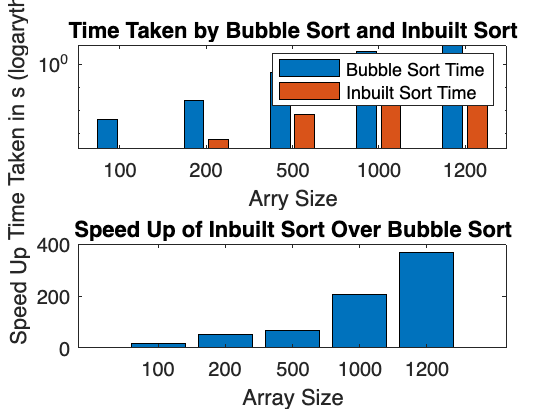

% Create a new figure
figure

% Create the first subplot
subplot(2,1,1)
% Create a bar graph of the time taken by the Bubble Sort function and MATLAB's built-in sort function
bar(cell2mat(timetaken(2:end ,2:3)));
% Add labels and title
xlabel('Arry Size')
ylabel('Time Taken in s (logarythmic)')
set(gca, 'YScale', 'log')
title('Time Taken by Bubble Sort and Inbuilt Sort')

% Change the x-axis labels to an array of your choice
xticklabels(timetaken(2:end,1))

% Add a legend
legend('Bubble Sort Time', 'Inbuilt Sort Time')


% Create the second subplot
subplot(2,1,2)
% Create a bar graph of the speed up
bar(cell2mat(timetaken(2:end ,4)));
% Add labels and title
xlabel('Array Size')
ylabel('Speed Up')
title('Speed Up of Inbuilt Sort Over Bubble Sort')

% Change the x-axis labels to an array of your choice
xticklabels(timetaken(2:end,1))

2.3.(c) Now for a bit of explicit parallelism (the MATLAB sort function tends to use implicit parallelism, i.e. you aren’t so aware of it being a parallel function). Use a parfor or spmd block to parallelize sorting of the columns of X. Test at least matrices of size 100, 5000 [15 marks]

% Initialize the cell array
testsizes = [100, 5000];
timetaken_par = cell(1+length(testsizes),4);
timetaken_par(1,:) = {"size", "bubble sort time", "inbuilt sort time", "speed up"};
timetaken_par(2:end,1) = num2cell(testsizes); % should use [100; 200; 500; 1000; 10000] but takes too long so using 1100 for know 

% Loop over each row in timetaken_par
for i = 2:size(timetaken_par,1)
    % Call the timetest function with the value in the first column of the i-th row
    timeBubble = timebubble_parallelism(timetaken_par{i,1});
   timeInbuilt = timesort_parallelism(timetaken_par{i,1}); 
    timetaken_par{i,2} = timeBubble;
    timetaken_par{i,3} = timeInbuilt;
    disp(i)
    % Calculate speed up
    timetaken_par{i,4} = timeBubble/timeInbuilt;
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 4 workers.



% Display the results
disp(timetaken_par)


Ploting bar graphs for this qustion 

% Create a new figure
figure

% Create the first subplot
subplot(2,1,1)
% Create a bar graph of the time taken by the Bubble Sort function and MATLAB's built-in sort function
bar(cell2mat(timetaken_par(2:end ,2:3)));
% Add labels and title
xlabel('Array Size')
ylabel('Time Taken in s (logarythic)')
set(gca, 'YScale', 'log')
title('Time Taken by the explicit parallelism Bubble Sort and Inbuilt Sort')

% Change the x-axis labels to an array of your choice
xticklabels(timetaken_par(2:end,1))

% Add a legend
legend('explicit parallelism Bubble Sort Time', 'explicit parallelism Inbuilt Sort Time')


% Create the second subplot
subplot(2,1,2)
% Create a bar graph of the speed up
bar(cell2mat(timetaken_par(2:end ,4)));
% Add labels and title
xlabel('Array Size')
ylabel('Speed Up')
title('Speed Up of explicit parallelism Inbuilt Sort over Bubble Sort')

% Change the x-axis labels to an array of your choice
xticklabels(timetaken_par(2:end,1))


% destroy parallel tools
p.delete;

Parallel pool using the 'Processes' profile is shutting down.
